% separate all the displacements
clear; clc;
addpath(genpath('functions'));

filePath = "D:\Research\experiments\ids results mat\20240529 IDS\DYA_A1J40.mat";
% filePath = "D:\Research\experiments\ids results mat\20240531 IDS\XA_Y3000_A3J80.mat";
% filePath = "D:\Research\experiments\ids results mat\20240601 IDS\XB_Y1500_A3J80.mat";
% filePath = "D:\Research\experiments\ids results mat\20240530 IDS\XD_Y3000A3J80.mat";
idsData = load(filePath);

figure;
plot(idsData.Time,idsData.Displacement);

## 位移分析

- 使用findpeaks函数，排除噪声并寻找所有局部最值。计算局部最值离理想值的差值，作为偏差

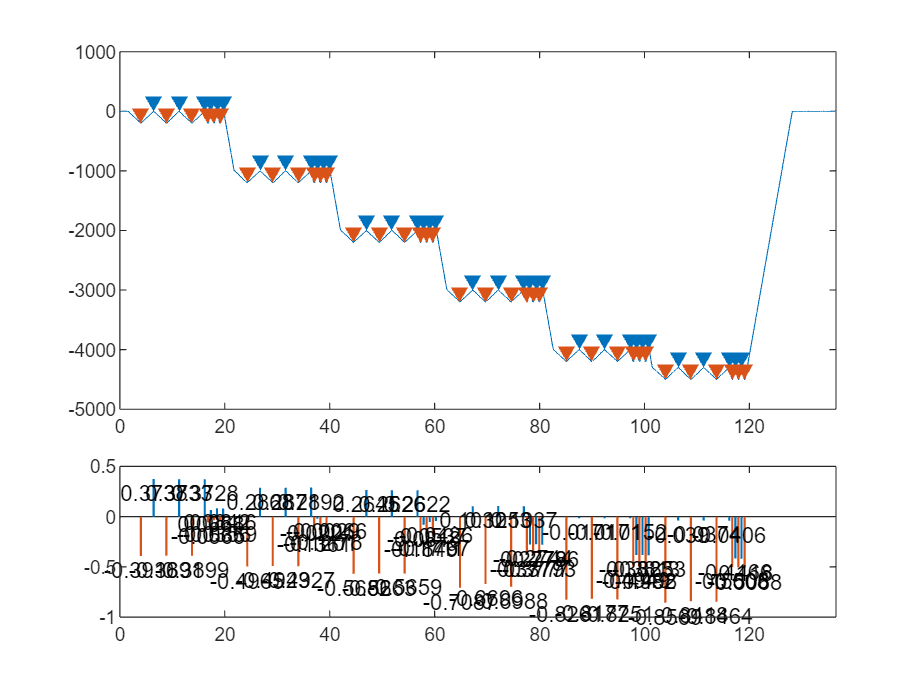

[idsPeaks,idsValleys] = displacement_segmentation(idsData.Time,idsData.Displacement);

## 速度分析

- 计算速度，然后把每一段速度的跃冲量和到平稳所需时间给计算出来

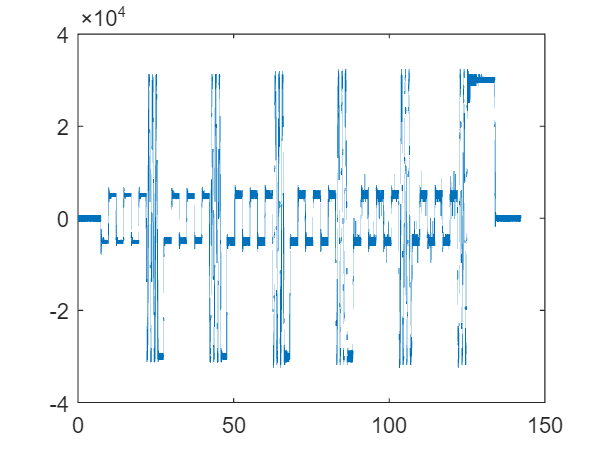

idsData.Velocity = 60*diff(idsData.Displacement) ./ diff(idsData.Time);
idsData.VelocityTime = 0.5*(idsData.Time(1:end - 1) + idsData.Time(2:end));
figure;
plot(idsData.VelocityTime,idsData.Velocity);

filter

错误使用 filter
输入参数的数目不足。

% rmpath(genpath('functions'));